# Taller IX

### 23/05/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 8 y 9*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

#### Integración Númerica

Para el taller de esta semana se solucionan dos de las seis integrales presentes, y dos de los cuatro ejercicios en $9\;y\;10$ del taller 9, se propone el uso de los métodos integrales y las propias herramientas de Matlab

**9) **Considere las siguientes funciones:


$$\begin{array}{l}
f\left(x\right)=\sin \left(x^2 \right)\;\cos \left(e^{2x} \right)\;\;:\;\;x\in \left\lbrack -2,1\right\rbrack \\
f\left(x\right)=\sin \left(\cos \left(e^{2\;x} \right)\right)\;\;\;\;\;\;\;:\;x\in \left\lbrack -5,1\right\rbrack \\
f\left(x\right)=\frac{1}{1+12\;x^2 }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;:\;x\in \left\lbrack -4,2\right\rbrack \\
f\left(x\right)=\frac{\cos \left(x\right)}{\ln \left(e^x +15\right)}\;\;\;\;\;\;\;\;\;\;\;:\;x\in \left\lbrack -1,11\right\rbrack \\
f\left(x\right)=\frac{\sin \left(x\right)}{\sqrt{x^2 +5}}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;:\;x\in \left\lbrack 0,7\pi \right\rbrack 
\end{array}$$


Aproximar el  valor de $\int_a^b f\left(x\right)\;\textrm{dx}$ por medio de la cuadratura de Gauss-Legendre con 2, 3, 4, 5, 6 nodos.

clear
syms f(x)

f1(x) = sin(x^2) * cos(exp(2*x));  % Definimos la función
f2(x) = sin(cos(exp(2*x)));        % Definimos la función
f3(x) = 1 / (1 + 12*x^2);          % Definimos la función
f4(x) = cos(x) / log(exp(x) + 15); % Definimos la función
f5(x) = sin(x) / sqrt(x^2 + 15);   % Definimos la función

f1 = matlabFunction(f1); % Transfomamos las funciones
f2 = matlabFunction(f2); % Transfomamos las funciones
f3 = matlabFunction(f3); % Transfomamos las funciones
f4 = matlabFunction(f4); % Transfomamos las funciones
f5 = matlabFunction(f5); % Transfomamos las funciones

% Evaluamos por medio de la cuadratura de Gauss-Legendre con 6 nodos.
I = GaussLegendre(f1, -2, 1, 6)
I = GaussLegendre(f2, -5, 1, 6)
I = GaussLegendre(f3, -4, 2, 6)
I = GaussLegendre(f4, -1, 11, 6)
I = GaussLegendre(f5, 0, 7*pi, 6)

**10) **Calcule el valor de las siguientes integrales impropias


$$\int_0^5 \frac{1}{\sqrt{x}}\mathrm{dx},\;\;\;\int_1^{\infty } e^{-x^2 } \;\mathrm{dx},\;\;\;\;\int_{-1}^{\infty } \frac{\sin^2 \left(y\right)}{e^y }\mathrm{dy},\;\;\;\int_2^{\infty } \frac{1}{\left(1\;+y^2 \right)\left(1+0\ldotp 5y^2 \right)}\mathrm{dx}$$
 

clear
syms f(x)

f1(x) = 1 / sqrt(x);                                % Definimos la función
f2(x) = - exp(-(1/x)^2) / x^2;                      % Definimos con cambio de variable: x = 1/t

I = 0.8521

f3(x) = - sin(1/x)^2 / exp(1/x) * 1/ x^2;           % Definimos con cambio de variable: x = 1/t

I = 4.3936

f4(x) = - 1 / ((1 + 1/x^2) * (1 + .5/x^2)) * 1/x^2; % Definimos con cambio de variable: x = 1/t

I = 0.8634

I = 0.2194

f1 = matlabFunction(f1); % Transfomamos las funciones

I = 0.6585

f2 = matlabFunction(f2); % Transfomamos las funciones
f3 = matlabFunction(f3); % Transfomamos las funciones
f4 = matlabFunction(f4); % Transfomamos las funciones

% Evaluamos por medio de la cuadratura de Gauss-Legendre con 6 nodos.
I = GaussLegendre(f1, 0, 5, 6), I = integral(f1, 0, 5)
I = GaussLegendre(f2, 1, 0, 10), I = integral(f2, 1, 0)
I = GaussLegendre(f3, -1, 0, 6), I = integral(f3, -1, 0)
I = GaussLegendre(f4, 1/2, 0, 6), I = integral(f4, 1/2, 0)

### Otros ejemplos sobre integración Númerica

El tema es un tanto denso, por lo que se proponen ejercicios extras con los que podemos repasar los conceptos vistos:

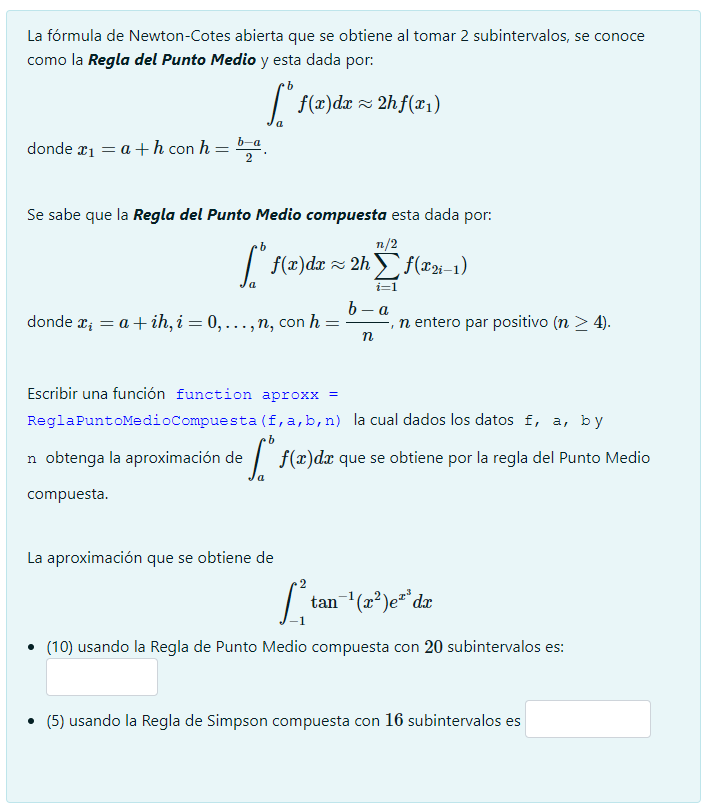

clear

% Definir la función:
f = @(x) atan(x.^2) .* exp(x.^3); % Función con @
a = -1; b = 2; n = 20; % Definimos los limites y pasos del método

aprox = puntomedio(f, a, b, n) % Definimos y ejecutamos Punto Medio
aproxSimp = simprl(f, -1, 2, 16) % Definimos y ejecutamos Simpson

**Código implementado (Punto medio):**

`function aprox = puntomedio(f, a, b, n)`

`% Entrada  - f funcion definida @`

`%          - a y b son los extremos del intervalo`

`%          - n Es la cantidad de intervalos presentes`

`% Salida   - aprox es la aproximación obtenida por el método`

`% Referencias`

`h = (b - a) / n;`

`s = 0;`

`for i = 1:(n/2)`

`    xi = a + (2*i - 1)*h;`

`    s = s + 2*h*feval(f, xi);`

`end`

`aprox = s;`

Cálcular el valor de la integral:


$$\int_{-\infty }^{\infty } e^{-x^2 } \;\tan^{-1} \left(3x-1\right)\;\mathrm{dx}$$


clear

I = 4.1725

I = 4.4721

syms f(x) g(x)

I = 0.1394

I = 0.1394

I = -5.1889e+14

I = -Inf

f(x) = exp(-x^2) * atan(3*x - 1);

I = 0.0569

I = 0.0569

g1(x) = .5* exp(-1 / (.5*x - .5) ^2) * atan(3/(.5*x - .5) - 1) + ...
    + .5* exp(-1 / (.5*x + .5) ^2) * atan(3/(.5*x + .5) - 1) + f(x);
g2(x) = f(x) + exp(-1/x^2) * atan(3/x - 1);

% Convertir la función.
f = matlabFunction(f);
g1 = matlabFunction(g1);
g2 = matlabFunction(g2);

[quad, raices, nodos, coefs] = GaussLegendre(g1, -1, 1, 10);
I = quad % Definición del valor

aprox = 234.5830

I = (1 - -1) / 2 * coefs' * f(nodos) % Definición del valor: Estandar

aproxSimp = 388.5442

I = GaussLegendre(g2, -1, 1, 10) % Definimos el valor de la integral
I = integral(f, -1, 1) % Hallamos el valor de la integral

### Solución númerica de ecuaciones diferenciales ordinarias

Para el taller de esta semana se solucionan dos ejercicios: $\left.\left.2\ldotp b\right)\;y\;c\right),y\;3\ldotp$

**2) **Determine las constantes de Lipschitz validas para todo $|t|\le 1$ para las siguientes funciones:


$$\begin{array}{l}
f\left(t,y\right)=t^4 \;y\\
f\left(t,y\right)=t\;e^{-y^2 } 
\end{array}$$


Hallamos analiticamente los valores, para ambos casos, se ejemplifica el segundo en esta caso usando criterios de derivada parcial.

clear
syms f(t, y)

f(t, y) = t * exp(- y^2); % Definimos la función
fy = diff(f, y) % Hallamos el valor de la derivada parcial on respecto a y
g(y) = -2*y*exp((-y^2)) % Buscamos acotar la contribución del termino de g(y)
% Hallamos los valores extremos
dg = diff(g, y); 
solve(dg(y) == 0)
L = abs(fy(1, sqrt(2) / 2)) % Reportamos el valor de las constante de Lipschitz

**3) **Utilice el método de Euler para resolver los problemas de valor inicial siguientes con los valores de $h$ indiciados. Como la solución correcta se conoce, tambien el error que se incurre:


$$\begin{array}{l}
y^{\prime } =\frac{y}{t}-{\left(\frac{y}{t}\right)}^2 ,\;\;1\le t\le 2,\;y\left(1\right)=1,\;h=0\ldotp 1\\
y^* \left(t\right)=\frac{t}{1+\ln \left(t\right)}
\end{array}$$


clear
syms f(t, y) g(t)

f(t, y) = y / t - (y / t)^2; % Definimos la función
f = matlabFunction(f); % Transormamos la función

I = -0.7215

I = -0.7075

M = (2 - 1) / .01; % No. de pasos

ans = -0.7215

ans = -0.7076

% Conozcamos el comportamiento del método
help euler
E = euler(f, 1, 2, 1, M); % Matriz de valores [X Y]
X = E(:, 1); % Valores de X
Y = E(:, 2); % Valores de Y

g(t) = t / (1 + log(t)); % Función de referencia

clf('reset')
hold on
fplot(g, [1, 2])
plot(X, Y, '.-')

$$fy(t, y) = -2\,t\,y\,{\mathrm{e}}^{-y^{2}}$$

grid on

$$g(y) = -2\,y\,{\mathrm{e}}^{-y^{2}}$$

hold off

Consideremos por otro lado la ecuación diferencial:


$$\begin{array}{l}
y^{\prime } =-\;\left(y+1\right)\;\left(y+3\right),\;\;0\le t\le 2,\;\;\;y\left(0\right)=-2,\;\;h\;=0\ldotp 2\\
y^* \left(t\right)=-3+\frac{2}{1+e^{-2\;t} }
\end{array}$$


clear
syms f(t, y) g(x)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

$$L = \sqrt{2}\,{\mathrm{e}}^{-\frac{1}{2}}$$

f(t, y) = - (y + 1)*(y + 3); % Definimos la función multivariada
g(t) = -3 + 2/ (1 + exp(-2*t)); % Definimos la función solución

f = matlabFunction(f); % Transformamos las funciones
g = matlabFunction(g); % Transformamos las funciones

M = (2 - 0) / .02; % No. de pasos

E = euler(f, 0, 2, -2, M) % Aplicamos el método, con matriz E = [X, Y]
X = E(:, 1); % Valores de X
Y = E(:, 2); % Valores de Y

clf('reset')

  Entrada  - f funcion creada con @
           - a y b son los extremos izquierdo y derecho
           - ya es la condicion inicial  y(a)
           - M es el numero de pasos
  Salida   - E = [T', Y'] donde T es el vector de abscisas y
             Y es el vector de ordenadas

    Other functions named euler



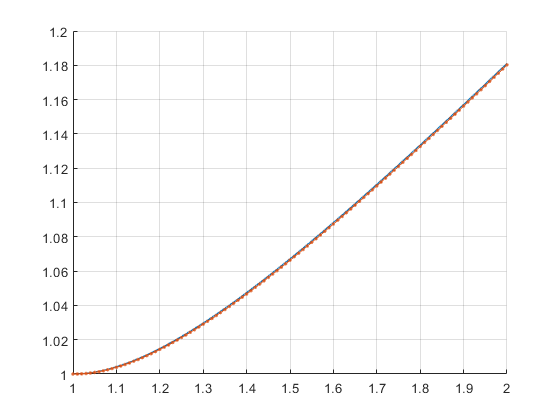

E =          0   -2.0000
    0.0200   -1.9800
    0.0400   -1.9600
    0.0600   -1.9400
    0.0800   -1.9201
    0.1000   -1.9002
    0.1200   -1.8804
    0.1400   -1.8607
    0.1600   -1.8411
    0.1800   -1.8216


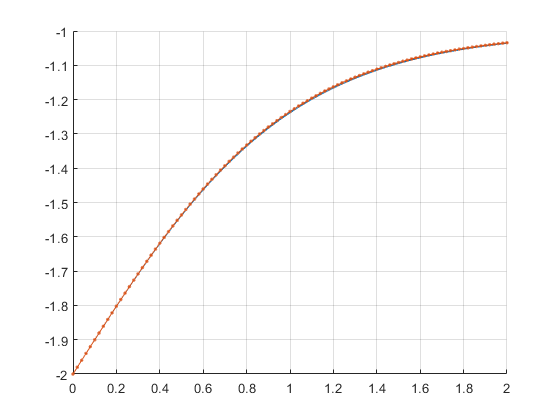

hold on
fplot(g, [0, 2])
plot(X, Y, '.-')
grid on
hold off